# Based on sinefeld and marom analytical method for the propagation of a gaussian beam on a pixelated SLM 

- Analysis of diffraction efficiency and crosstalk by means of fiber output position (delta_pos) and position that the beam is reflected by the SLM (delta)

- Basic Principle: when delta = delta_pos coupling efficiency to the chosen output value, while for different values of deltas crosstalk to other ports

- Meaning of the used parameters: pixel = pixel pitch, fiber_port = distance between ports, ports: -4 denotes -4th diffraction order (upper port) etc., omega = spot size on SLM, fl : focus length

- Exported parameters: Eout: power-coupling efficiency & cp: spectral tranmittance (dB)

clear all; clc
Eout = 0; Eout2 = 0; pixel = 6.4e-6;
omega=10e-6;lamda=1550e-9; 
iter = 0; theta=3; fiber_port=1.25e-3; fl = 0.035; delta =  fiber_port*(2);
ports=-4:4;
for jj = 1:length(ports)
    lamda_factor(jj) = (lamda*fl)/(delta*pixel);
    delta_pos = fiber_port*ports(jj)
    phi(jj) = delta_pos/fl;
for pix_count = -500:500 
    iter = iter + 1;  
    A_term = 0.5*exp(-0.5*((pi*omega*delta_pos)/(fl*lamda))^2);
    phase_d = ((2*pi)/lamda_factor(jj))*pix_count;
    C_factor=erfz((lamda*pixel*(2*pix_count+1)-1*j*pi*omega^2*phi(jj))/(sqrt(2)*lamda*omega))-...
    erfz((lamda*pixel*(2*pix_count-1)-1*j*pi*omega^2*phi(jj))/(sqrt(2)*lamda*omega));
    Eout = Eout + A_term*exp(-1*j*phase_d)*C_factor;
    keep(iter,jj) = exp(-1*j*phase_d);
end
cp(jj) = 10*log(abs(Eout).^2);
Eout = 0; iter = 0; output_efficiency = 0; C_factor=0;
end

delta_pos = -0.0050

delta_pos = -0.0038

delta_pos = -0.0025

delta_pos = -0.0013

delta_pos = 0

delta_pos = 0.0013

delta_pos = 0.0025

delta_pos = 0.0038

delta_pos = 0.0050

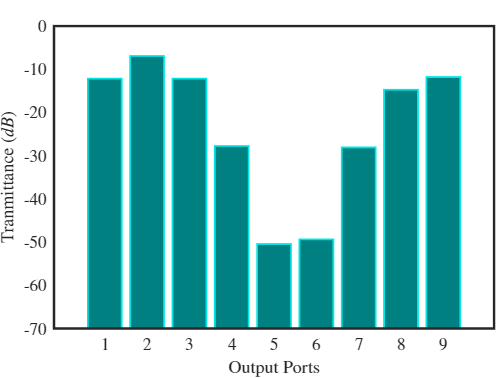

figure; 
b = bar(cp,'FaceColor',[0 .5 .5],'EdgeColor',[0 .9 .9],'LineWidth',1.5);
b(1).BaseValue = -70;
xlabel ('Output Ports','Interpreter','latex');ylabel ('Tranmittance $(dB)$','Interpreter','latex');
set(gca,'Linewidth',2);set(gca,'TickLabelInterpreter','latex');set(gca,'TickLength',[0, 0]);set(gca,'LooseInset',max(get(gca,'TightInset'), 0.02))
ax=gca;ax.FontSize=14;pos=get(gca,'pos');set(gca,'pos',[pos(1) pos(2) pos(3) pos(4)*.95]);

print('crosstalk','-dsvg','-r600') % save high-quality figure

`Christos Tselios, PhD student ece uop X ISI, project: LCOS X WSS (part II)`